**1.Alternate Sum**

myalternatesum(20)

ans = 10

myalternatesum(100)

ans = 50

**2.Format Long/Short**

f = @(x) 0.5*(x-1)^2;
format long
f(sqrt(3))

ans =    0.267949192431123


format short
f(sqrt(3))

ans = 0.2679

**3.Linspace graph**

f = @(x) 0.5*(x-1).^2;
x=linspace(0,1,10)

x =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


y=linspace(0,1,100)

y =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


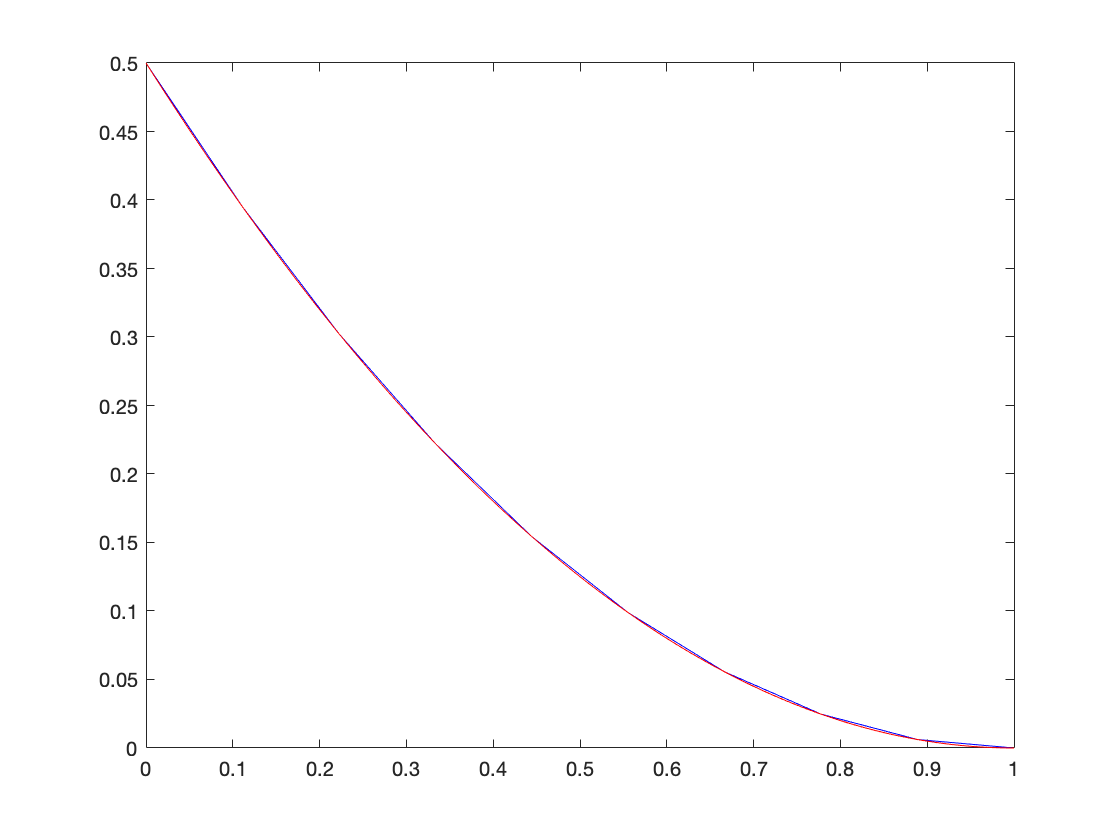

plot(x,f(x),'b',y,f(y),'r')

**4.Absolute error= va-ve**

Actual = (x-1)=.1

((f(1.1+.1)-f(1.1))/.1)-.1

ans = -0.0500

((f(1.1+.01)-f(1.1))/.01)-.1

ans = -0.0050

((f(1.1+.001)-f(1.1))/.001)-.1

ans = -5.0000e-04

**5.Comparing graphs**

x=linspace(0,1.1,100)

x =          0    0.0111    0.0222    0.0333    0.0444    0.0556    0.0667    0.0778    0.0889    0.1000    0.1111    0.1222    0.1333    0.1444    0.1556    0.1667    0.1778    0.1889    0.2000    0.2111    0.2222    0.2333    0.2444    0.2556    0.2667    0.2778    0.2889    0.3000    0.3111    0.3222    0.3333    0.3444    0.3556    0.3667    0.3778    0.3889    0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000    0.5111    0.5222    0.5333    0.5444


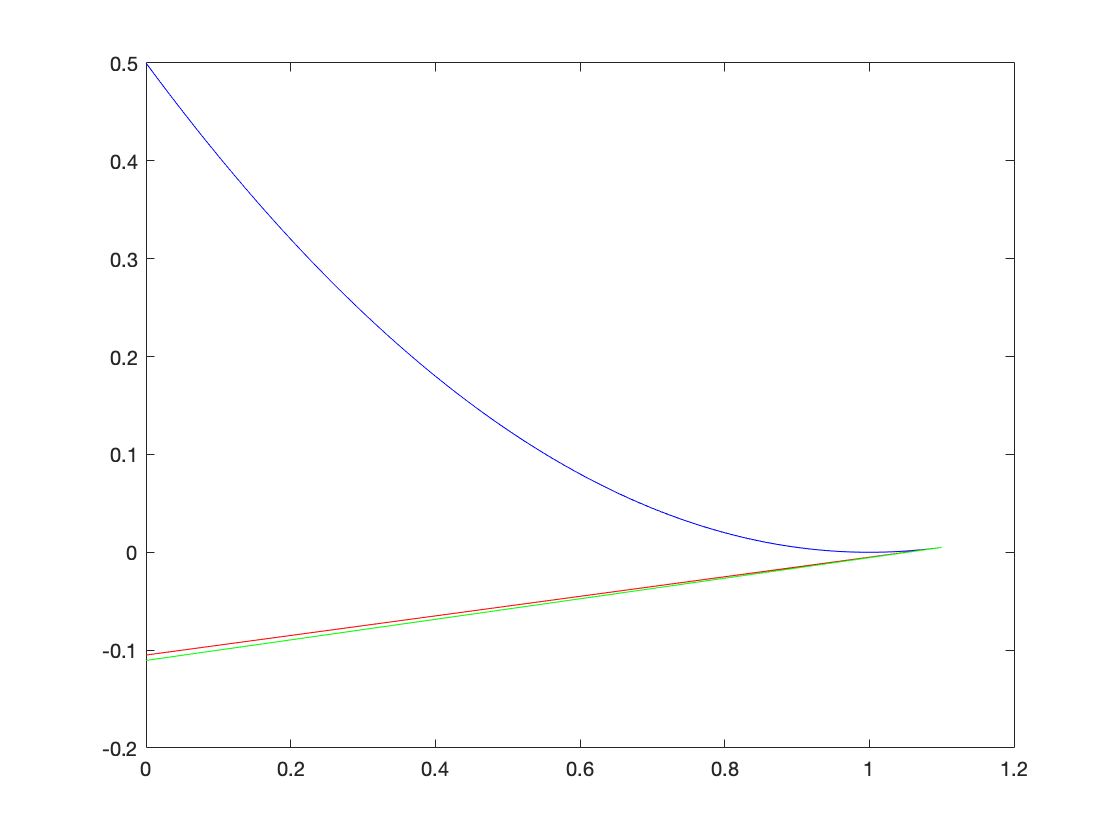

plot(x,f(x),'b',x,.1*x -.105,'r',x,.105*x-.1105,'g')

**Helper Functions**

function [o]= myalternatesum(n)
%Use the formula  to compute alternating sums through use of a for loop
%Using the  integer (n) we can calculate alternating sums
o=0;
for i=1:n
    o=o+(-1)^i*i;
end
end